# DS-SS/QPSK変復調システム

前提条件

- AWGN通信路

- SN比: 0dB

- 帯域幅: 25Hz

- 搬送波周波数: 50Hz

- サンプリング周波数: 1kHz

- ビットレート: 25Hz

- チップレート: 250Hz

- 拡散比: 10

## ワークスペースの初期化

clear
close all
clc

## 図のフォント設定

set(0, 'defaultAxesFontSize', 14);
set(0, 'defaultAxesFontName', 'times');
set(0, 'defaultTextFontSize', 14);
set(0, 'defaultTextFontName', 'times');

## パラメータの設定

CARRIER_FREQ = 500;
MULTIPLE_LEVEL = 2;

bitRate = 25;
chipRate = 10*bitRate;

snRatio = 0;

samplingFreq = 20*CARRIER_FREQ;
samplingPeriod = 1/samplingFreq;

timePeriod = 1/bitRate;
chipPeriod = 1/chipRate;
spreadRate = floor(timePeriod/chipPeriod);
bitsPerSymbol = log2(MULTIPLE_LEVEL);

filterSpan = 6;
samplesPerSymbol = floor(chipPeriod/samplingPeriod);
filterDA = rcosdesign(0.5, filterSpan, samplesPerSymbol, 'sqrt');
filterDelay = mean(grpdelay(filterDA))*((samplesPerSymbol-filterSpan/2)/samplesPerSymbol);

t = 0:1/samplingFreq:chipPeriod-1/samplingFreq;

## 入力ビット列の確認

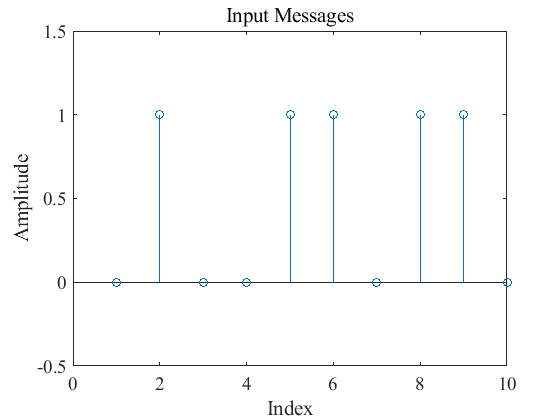

messages = [0 1 0 0 1 1 0 1 1 0];

stem(messages)
ylim([-0.5 1.5])
title('Input Messages')
xlabel('Index')
ylabel('Amplitude')

## 変調シンボル列の確認

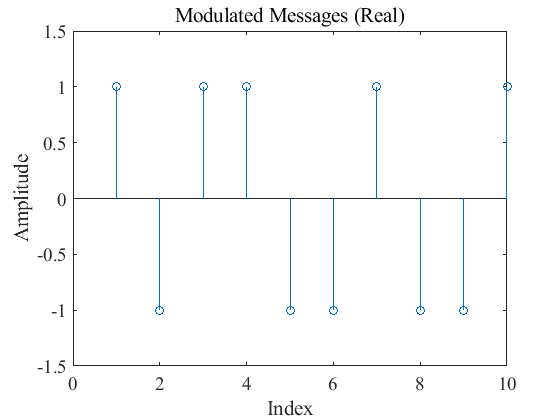

infoBinary = messages';
infoDecimal = bi2de(infoBinary, 'left-msb');
infoModulated = pskmod(infoDecimal, MULTIPLE_LEVEL, 0, 'gray');

stem(real(infoModulated))
ylim([-1.5 1.5])
title('Modulated Messages (Real)')
xlabel('Index')
ylabel('Amplitude')

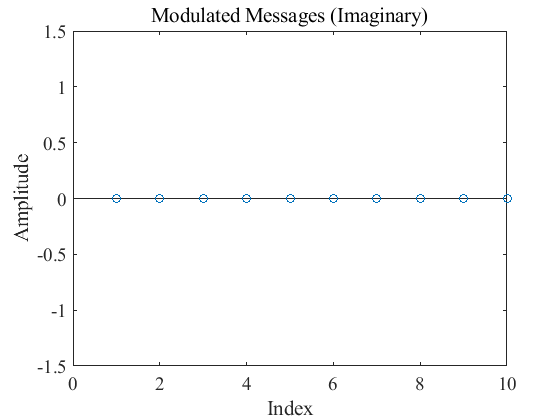

stem(imag(infoModulated))
ylim([-1.5 1.5])
title('Modulated Messages (Imaginary)')
xlabel('Index')
ylabel('Amplitude')

## 疑似雑音信号の確認

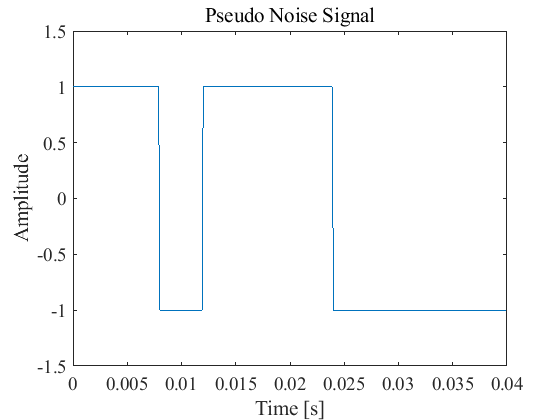

rng('shuffle')
pseudoNoise =  2*randi([0 1], 1, spreadRate) - 1;

pseudoNoiseContinuous = zeros(1, size(pseudoNoise,2)*size(t,2));
for k = 1:1:length(pseudoNoise)
    pseudoNoiseContinuous(1+(k-1)*size(t,2):k*size(t,2)) = pseudoNoise(k);
end

plot((0:samplingPeriod:length(pseudoNoise)*chipPeriod-samplingPeriod), pseudoNoiseContinuous)
ylim([-1.5 1.5])
title('Pseudo Noise Signal')
xlabel('Time [s]')
ylabel('Amplitude')

## 離散時間DS-SS信号の確認

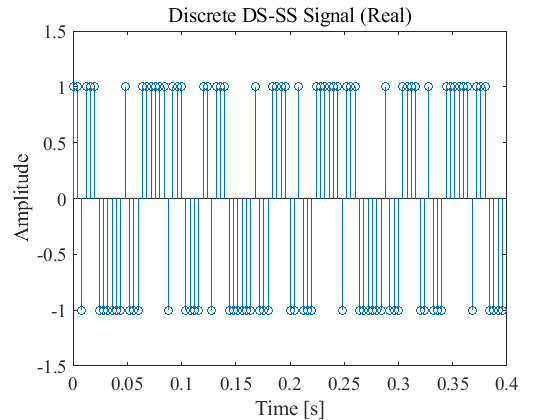

dsssDiscrete = zeros(1, size(infoModulated,2));
for k = 1:1:length(infoModulated)
    dsssDiscrete(1+(k-1)*spreadRate:k*spreadRate) = infoModulated(k).*pseudoNoise;
end

stem((0:chipPeriod:(length(infoModulated)*length(pseudoNoise)-1)*chipPeriod), real(dsssDiscrete))
ylim([-1.5 1.5])
title('Discrete DS-SS Signal (Real)')
xlabel('Time [s]')
ylabel('Amplitude')

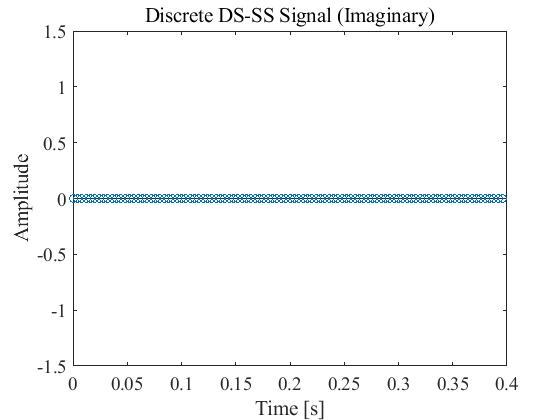

stem((0:chipPeriod:(length(infoModulated)*length(pseudoNoise)-1)*chipPeriod), imag(dsssDiscrete))
ylim([-1.5 1.5])
title('Discrete DS-SS Signal (Imaginary)')
xlabel('Time [s]')
ylabel('Amplitude')

## 連続時間DS-SS信号の確認

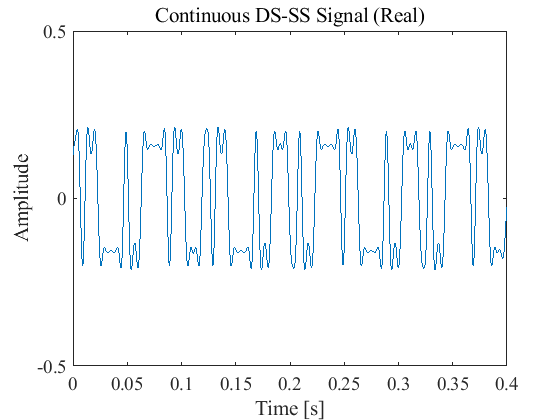

tt = 0:1/samplingFreq:length(dsssDiscrete)*chipPeriod-1/samplingFreq;

dsssSignalContinuousTilde = upfirdn(dsssDiscrete, filterDA, samplesPerSymbol);
dsssSignalContinuousTilde(1:filterDelay) = [];
dsssSignalContinuous = dsssSignalContinuousTilde(1:length(tt));

plot(tt, real(dsssSignalContinuous))
ylim([-0.5 0.5])
title('Continuous DS-SS Signal (Real)')
xlabel('Time [s]')
ylabel('Amplitude')

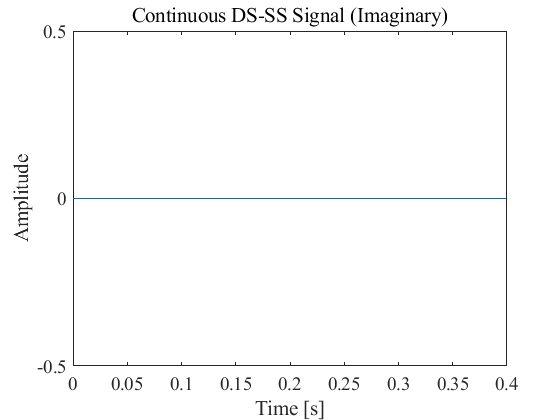

plot(tt, imag(dsssSignalContinuous))
ylim([-0.5 0.5])
title('Continuous DS-SS Signal (Imaginary)')
xlabel('Time [s]')
ylabel('Amplitude')

## DS-SS信号の確認

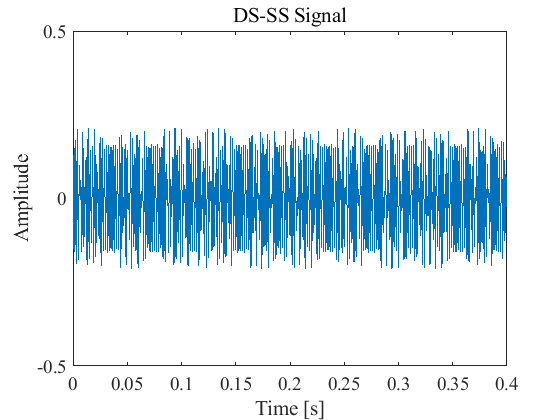

dsssSignalTilde = dsssSignalContinuous.*exp(1i*2*pi*CARRIER_FREQ*tt);

dsssSignal = real(dsssSignalTilde);

plot(tt, dsssSignal)
ylim([-0.5 0.5])
title('DS-SS Signal')
xlabel('Time [s]')
ylabel('Amplitude')

## 雑音印加後の信号確認

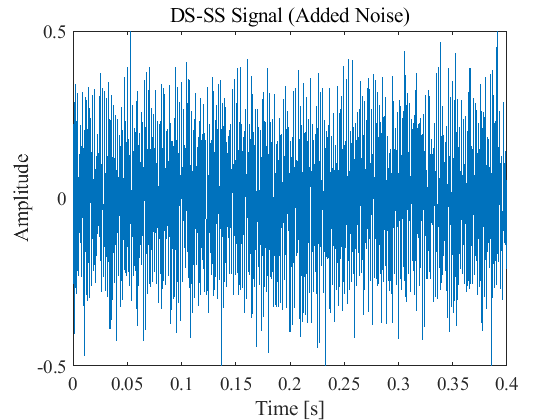

rng('shuffle')
signalAddedNoise = awgn(dsssSignal, snRatio, 'measured');  % signalAddedNoise = dsssSignal;

plot(tt, signalAddedNoise)
ylim([-0.5 0.5])
title('DS-SS Signal (Added Noise)')
xlabel('Time [s]')
ylabel('Amplitude')

## 復調シンボル列の確認

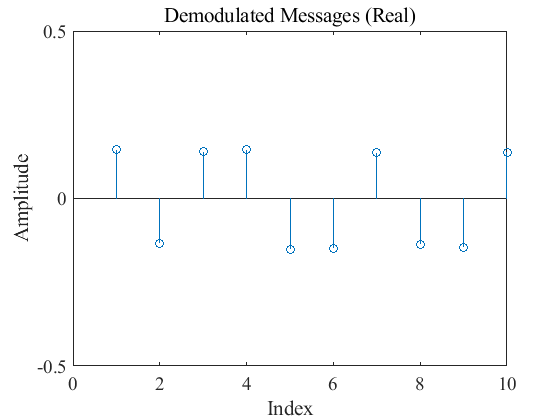

signalInverse = signalAddedNoise.*exp(-1i*2*pi*CARRIER_FREQ*tt);

signalLPF = zeros(1, size(infoModulated,2));
for k = 1:length(infoModulated)
    signalLPF(k) = sum(signalInverse(1+(k-1)*size(t,2)*spreadRate:k*size(t,2)*spreadRate).*pseudoNoiseContinuous)*(2/(timePeriod*samplingFreq));
end

stem(real(signalLPF))
ylim([-0.5 0.5])
title('Demodulated Messages (Real)')
xlabel('Index')
ylabel('Amplitude')

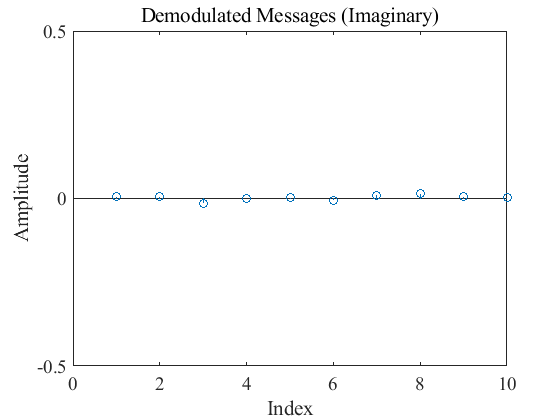

stem(imag(signalLPF))
ylim([-0.5 0.5])
title('Demodulated Messages (Imaginary)')
xlabel('Index')
ylabel('Amplitude')

## 出力ビット列の確認

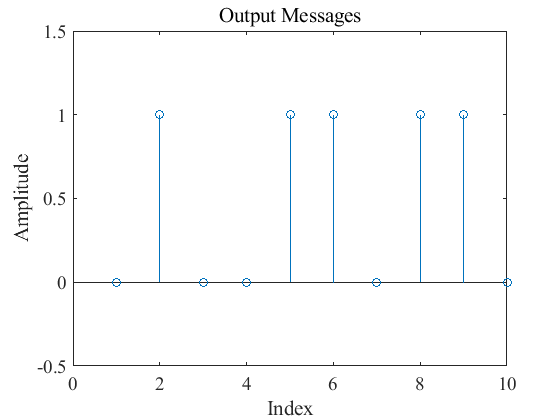

receivedInfoDecimal = pskdemod(signalLPF.', MULTIPLE_LEVEL, 0, 'gray');
receivedInfoBinary = de2bi(receivedInfoDecimal, bitsPerSymbol, 'left-msb');
recievedMessagesTilde = receivedInfoBinary';
recievedMessages = recievedMessagesTilde(:)';

stem(recievedMessages)
ylim([-0.5 1.5])
title('Output Messages')
xlabel('Index')
ylabel('Amplitude')

## ビット誤り率の確認

bitErrorRate = biterr(messages, recievedMessages)/length(messages)

bitErrorRate = 0